##  1 获取鼠标在全屏位置

屏幕左上角为坐标原点，获取鼠标位置和获取鼠标像素颜色建议和while循环或者timer函数结合使用：

import java.awt.MouseInfo;
mousepoint=MouseInfo.getPointerInfo().getLocation();
mousepoint=[mousepoint.x,mousepoint.y]

mousepoint =   -256    23


## 2 获取剪切板当前内容

import java.awt.Toolkit
import java.awt.datatransfer.DataFlavor
clip=Toolkit.getDefaultToolkit().getSystemClipboard();

clipTf=clip.getContents([]);
clipContent=clipTf.getTransferData(DataFlavor.stringFlavor)

clipContent = '欢迎关注slandarer随笔'

## 3 内容复制到剪切板


import java.awt.Toolkit;
import java.awt.datatransfer.StringSelection;
clip=Toolkit.getDefaultToolkit().getSystemClipboard();

contentStr='欢迎关注slandarer随笔';

tText=StringSelection(contentStr);
clip.setContents(tText,[]); 


## 4 获取鼠标处像素颜色

需要和获取鼠标位置的函数结合。获取结果数值范围为[0,255]；


import java.awt.MouseInfo;
import java.awt.Robot;
robot=Robot();

mousepoint=MouseInfo.getPointerInfo().getLocation();
tempColor=robot.getPixelColor(mousepoint.x, mousepoint.y);
RGBColor=[tempColor.getRed(),tempColor.getGreen(),tempColor.getBlue()]

RGBColor =    255   255   255


## 5 获取屏幕截图

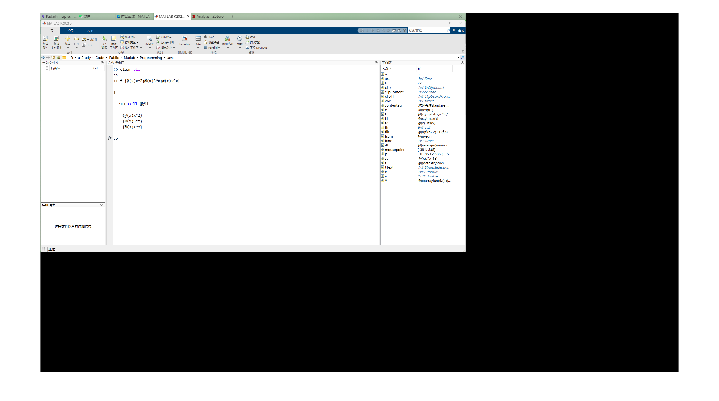


import java.awt.Robot;
import java.awt.Rectangle;
robot=Robot();
rectangle=Rectangle();

screensize=get(0,'screensize');
screensize=1.5*screensize;
rectangle.x=0;
rectangle.y=0;
rectangle.width=screensize(3);
rectangle.height=screensize(4);

image=robot.createScreenCapture(rectangle);
data=image.getData();
temp=zeros(screensize(3)*screensize(4)*3,1);
temp=data.getPixels(0,0,screensize(3),screensize(4),temp);
temp=uint8(temp);
R=temp(1:3:end);
G=temp(2:3:end);
B=temp(3:3:end);
R=reshape(R,[screensize(3),screensize(4)]);
G=reshape(G,[screensize(3),screensize(4)]);
B=reshape(B,[screensize(3),screensize(4)]);
R=R';G=G';B=B';
ima=cat(3,R,G,B);

imshow(ima)

## 6 创建JAVA窗口(并使其永远在最上方)

关于按钮怎么创建请看第七部分。

import java.awt.Frame;
import java.awt.Point;

frame=Frame();

% 设置java窗口大小
frame.setSize(400,300)
% 设置java窗口位置
point=Point(300,200);
frame.setLocation(point)

% 使其永远在最上方
frame.setAlwaysOnTop(true);

% 设置窗口关闭回调(不设置的话java frame将无法关闭)
hjWindow=handle(frame,'CallbackProperties');
set(hjWindow,'WindowClosingCallback',@(h,e)frame.dispose());

% 显示java窗口
frame.setVisible(true)

## 7 创建透明窗口并安置按钮

值得一提的是get函数可以获取对象的属性，methods函数可以获取对象的方法，以下给出一个创建按钮并修改其属性，创建回调的方式：

import java.awt.Frame;
import java.awt.Point;
import java.awt.Button;
import java.awt.Font;

frame=Frame();

% 设置java窗口大小
frame.setSize(400,200)
% 设置java窗口位置
point=Point(50,400);
frame.setLocation(point)

% 因为要依据数值设置按钮位置，因此setLayout(NULL)
frame.setLayout([]);

bt1=Button("点我试试");
bt2=Button("关闭窗口");

% 设置点击事件
hbt1=handle(bt1,'CallbackProperties');
set(hbt1,'MousePressedCallback',@(h,e)disp('欢迎关注公众号slandarer随笔'))

hbt2=handle(bt2,'CallbackProperties');
set(hbt2,'MousePressedCallback',@(h,e)frame.dispose())

% 设置按钮字体及字号
mf=Font('宋体',Font.BOLD,25);
bt1.setFont(mf)
bt2.setFont(mf)

% 设置按钮位置
bt1.setLocation(30,30);
bt1.setSize(140,140);
bt2.setLocation(220,30);
bt2.setSize(140,140);

% 添加按钮
frame.add(bt1);
frame.add(bt2);

% 取消边框并设置透明度
frame.setUndecorated(true);
frame.setOpacity(.7);

% 设置窗口关闭回调
hjWindow=handle(frame, 'CallbackProperties');
set(hjWindow, 'WindowClosingCallback', @(h,e)frame.dispose());

% 显示java窗口
frame.setVisible(true)